clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459

data.CzasLokalnyUTC0000(1:4)

ans = 4×1 datetime array
   NaT                
   15/03/2024 11:00:09
   15/03/2024 11:00:14
   15/03/2024 11:00:19


data.CzasLokalnyUTC0000(n-3:n)

ans = 4×1 datetime array
   16/04/2024 08:49:27
   16/04/2024 08:49:32
   16/04/2024 08:49:37
   NaT                


We see data was collected for over a month. For now let's just take a day.

From time vector:

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

ZawrOdszraniania=data.ZawrOdszraniania;
Kompresor1=data.Kompresor1;
WentylatorParownika=data.WentylatorParownika;
PunktNastawyA=data.PunktNastawyA;
Rozmraanie=data.Rozmraanie;
TemperaturaOtoczenia=data.TemperaturaOtoczenia;
Skraplacz=data.Skraplacz;
Wlot=data.Wlot;
Parownik1=data.Parownik1;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,PunktNastawyA,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';
size(X_all)

ans =            9      516459


day=24*60*60*fs

day = 17280

t=T*(1:day);
X=X_all(:,1:day);
size(X)

ans =            9       17280


[dataWithoutNans,nan_indices]  = GetRidOfNans(X);

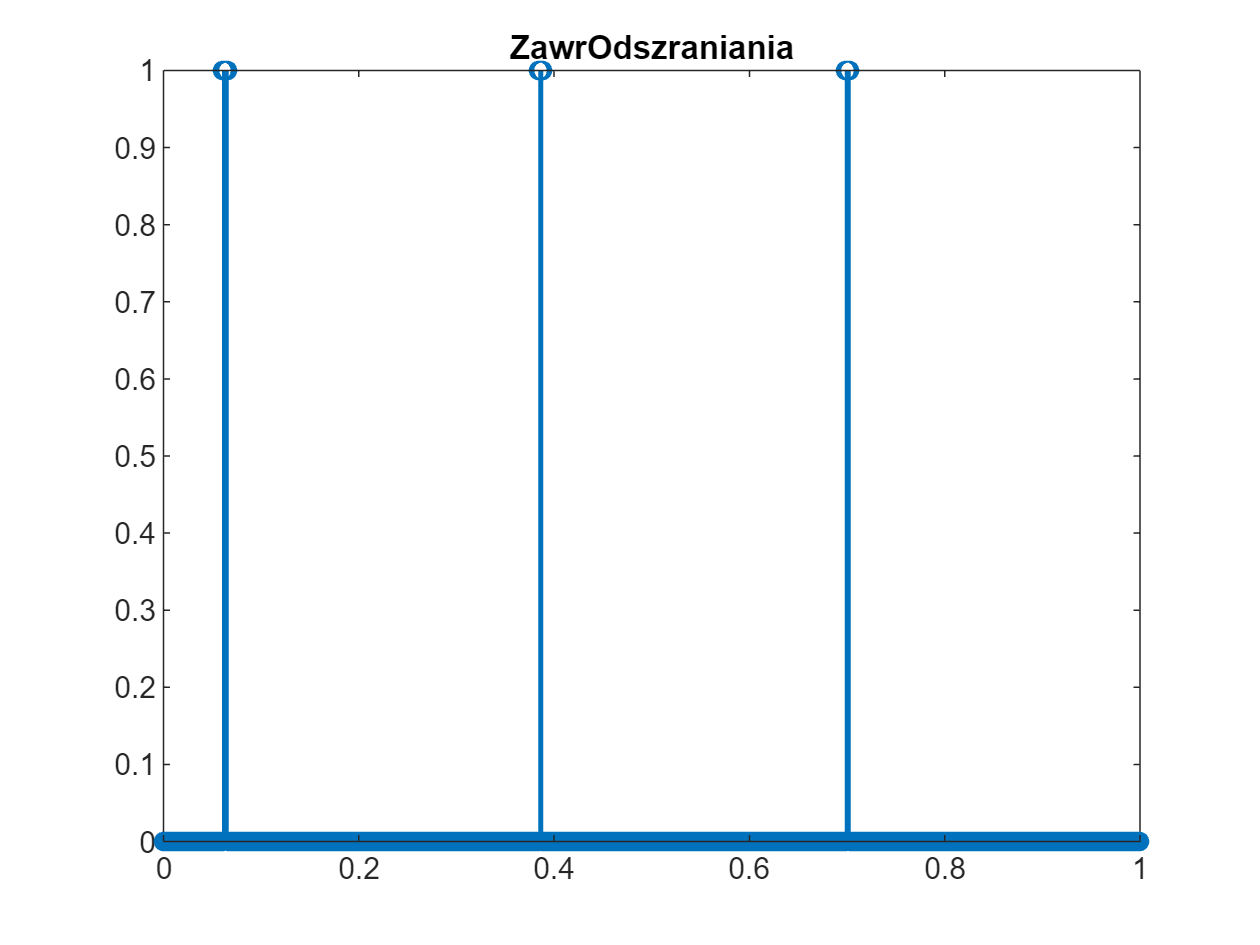

stem(t./(60*60*24),X(1,:))
title('ZawrOdszraniania')

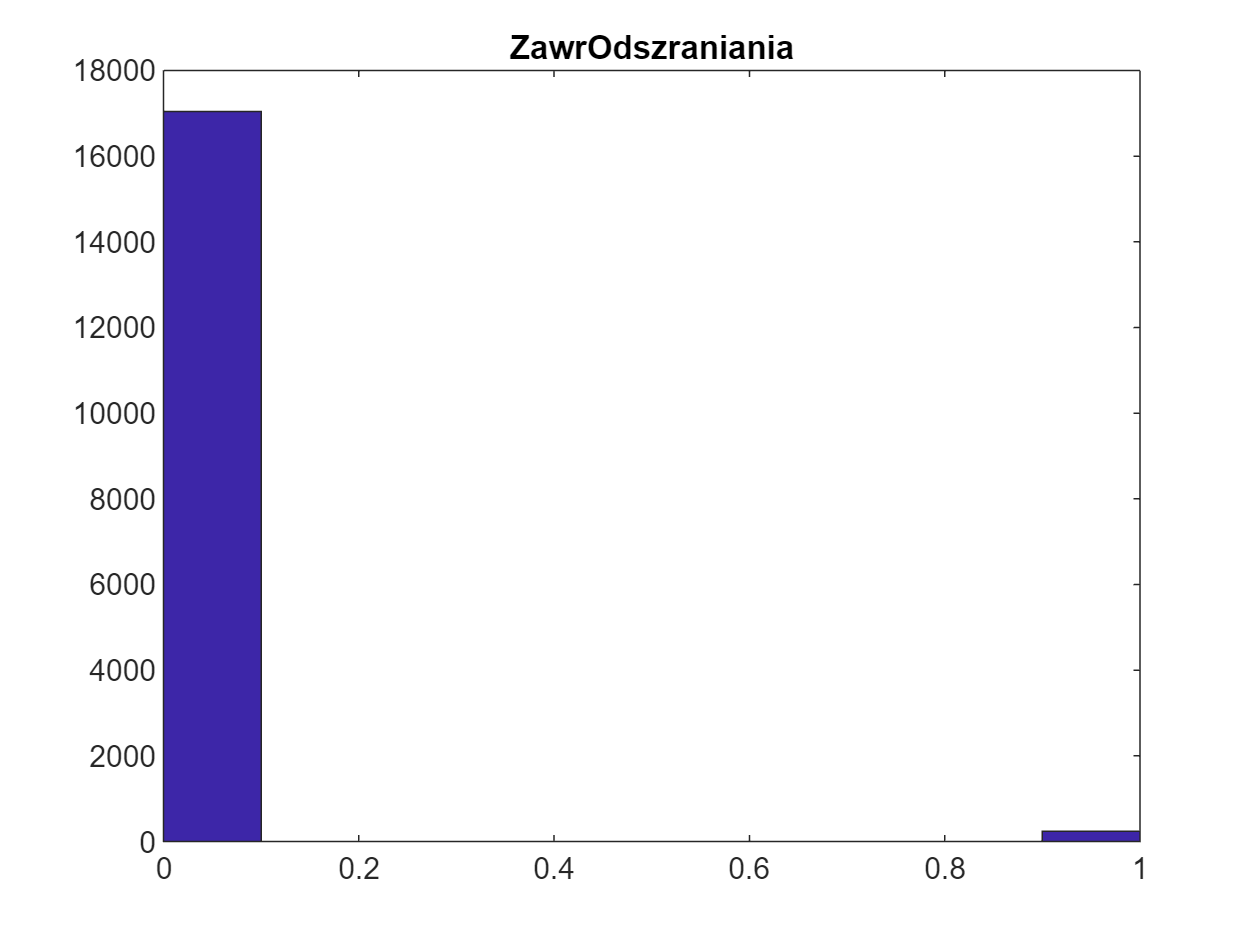

hist(X(1,:))
title('ZawrOdszraniania')

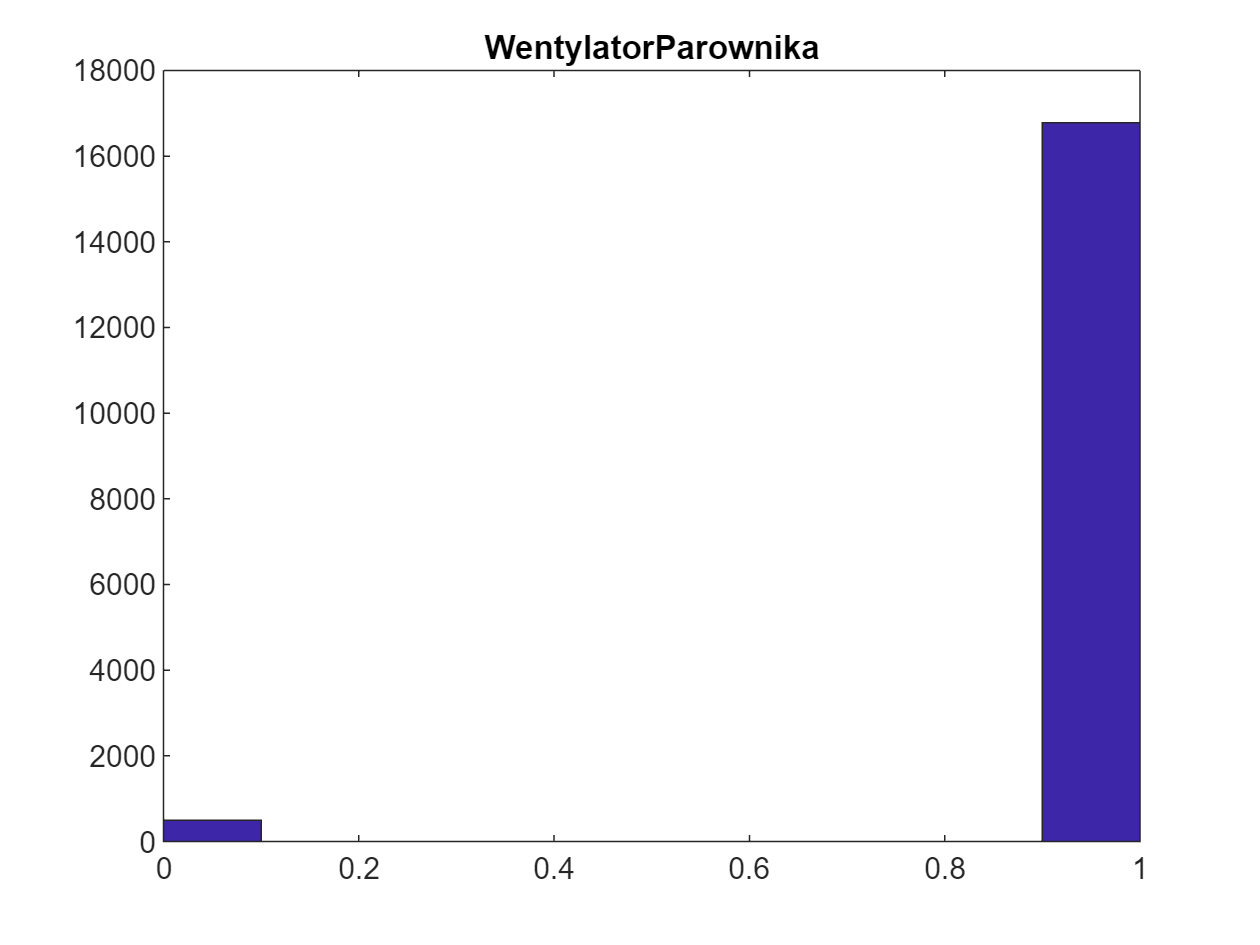

hist(X(3,:))
title('WentylatorParownika')

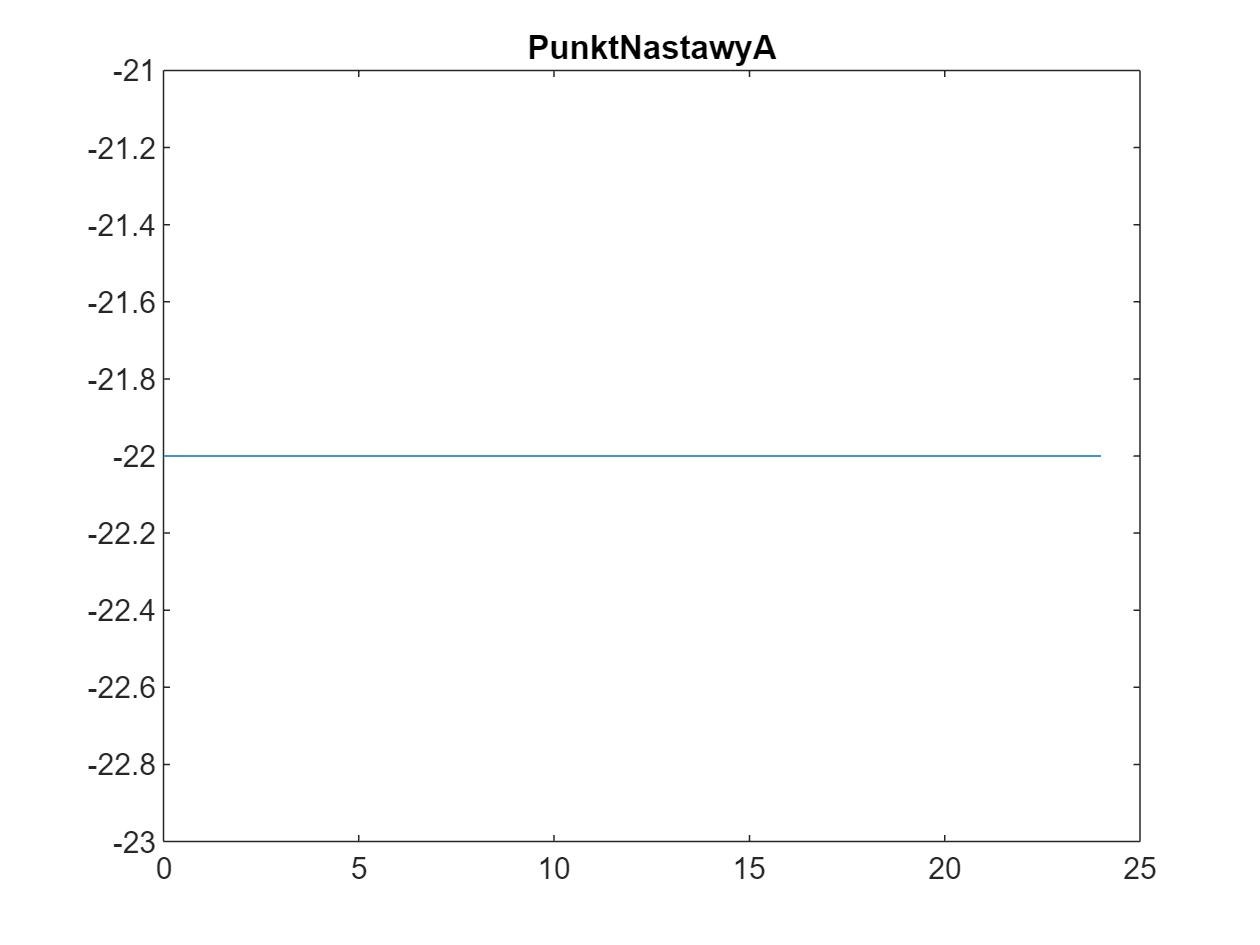

plot(t/(60*60),X(4,:))
title('PunktNastawyA')

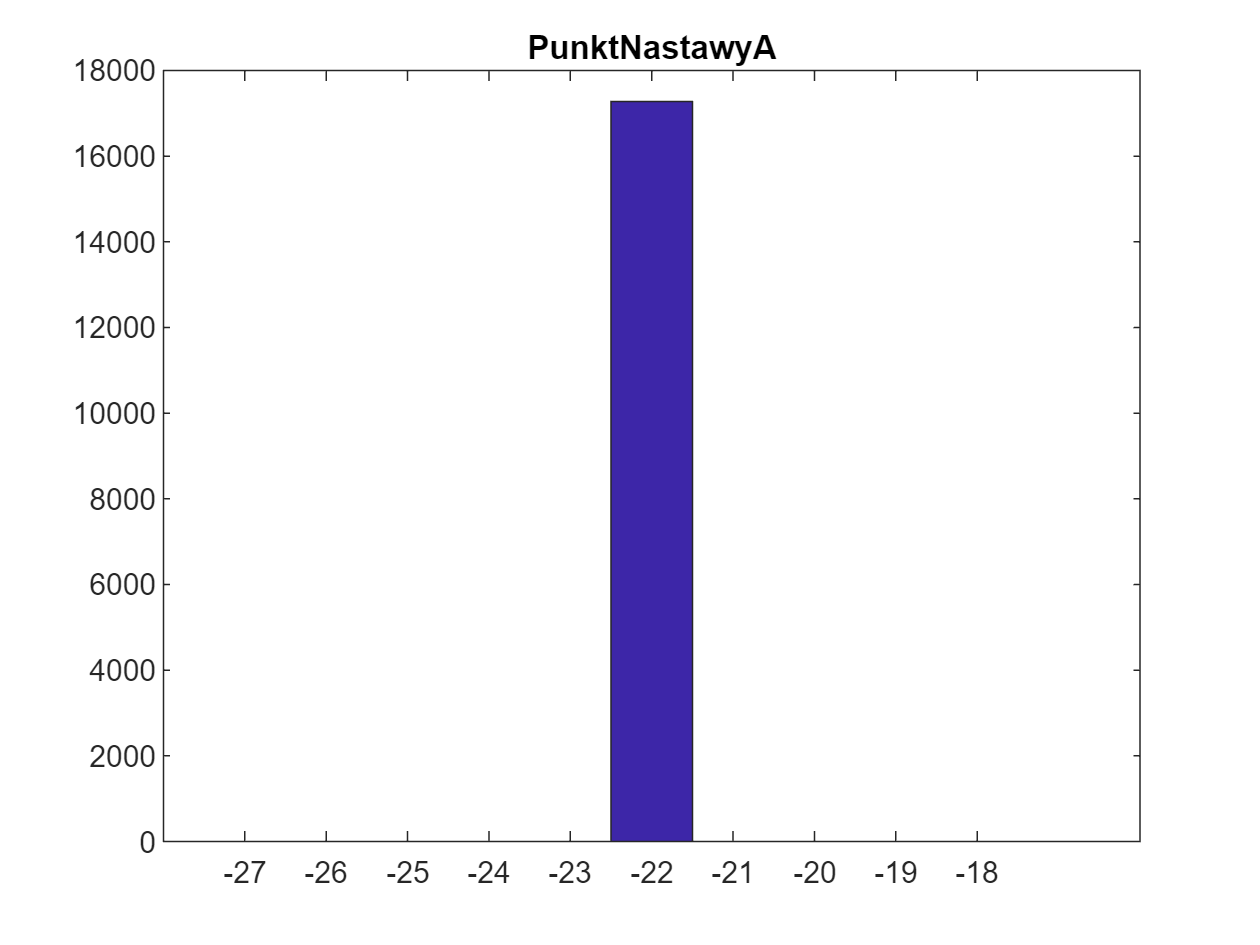

hist(X(4,:))
title('PunktNastawyA')

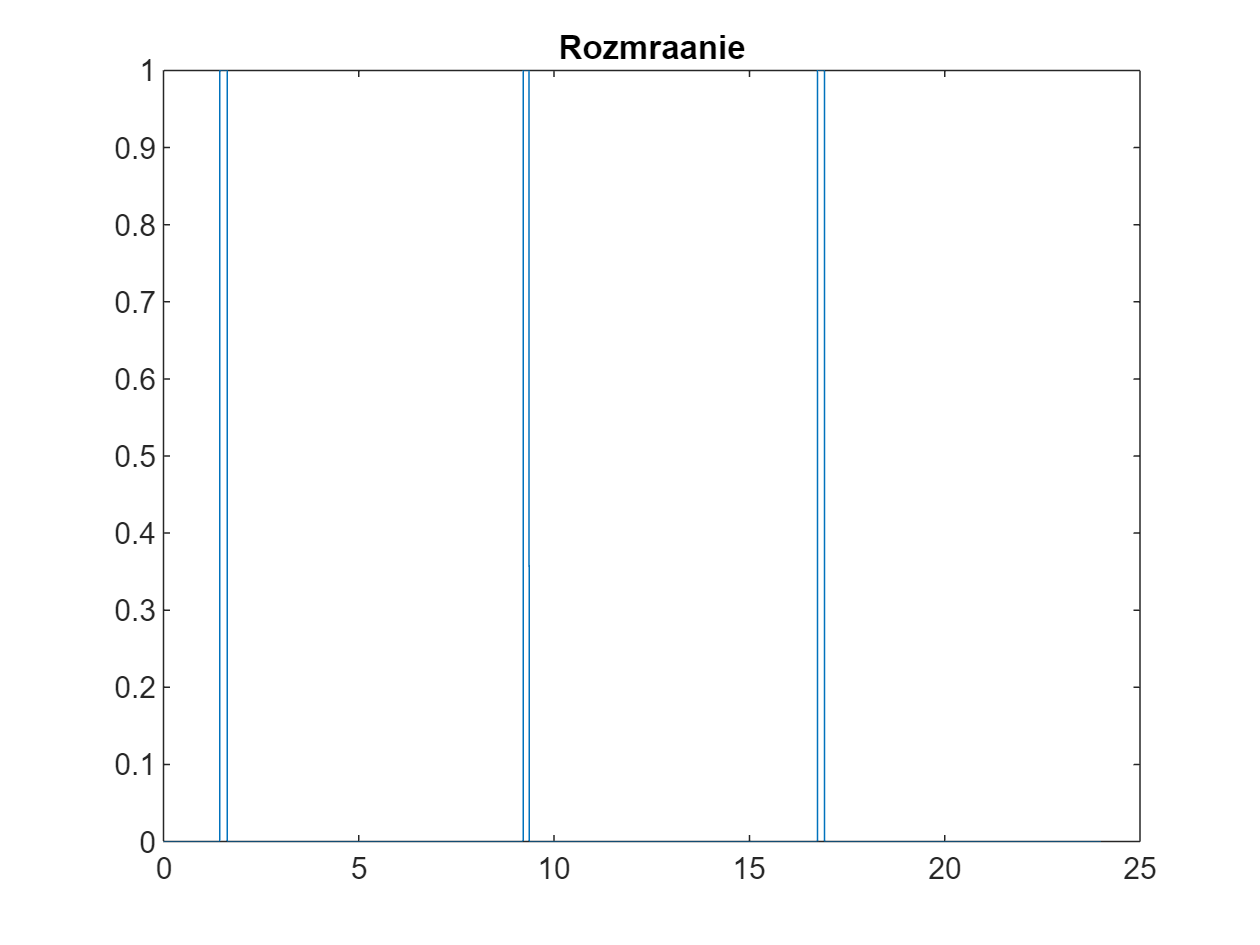

plot(t/(60*60),X(5,:))
title('Rozmraanie')

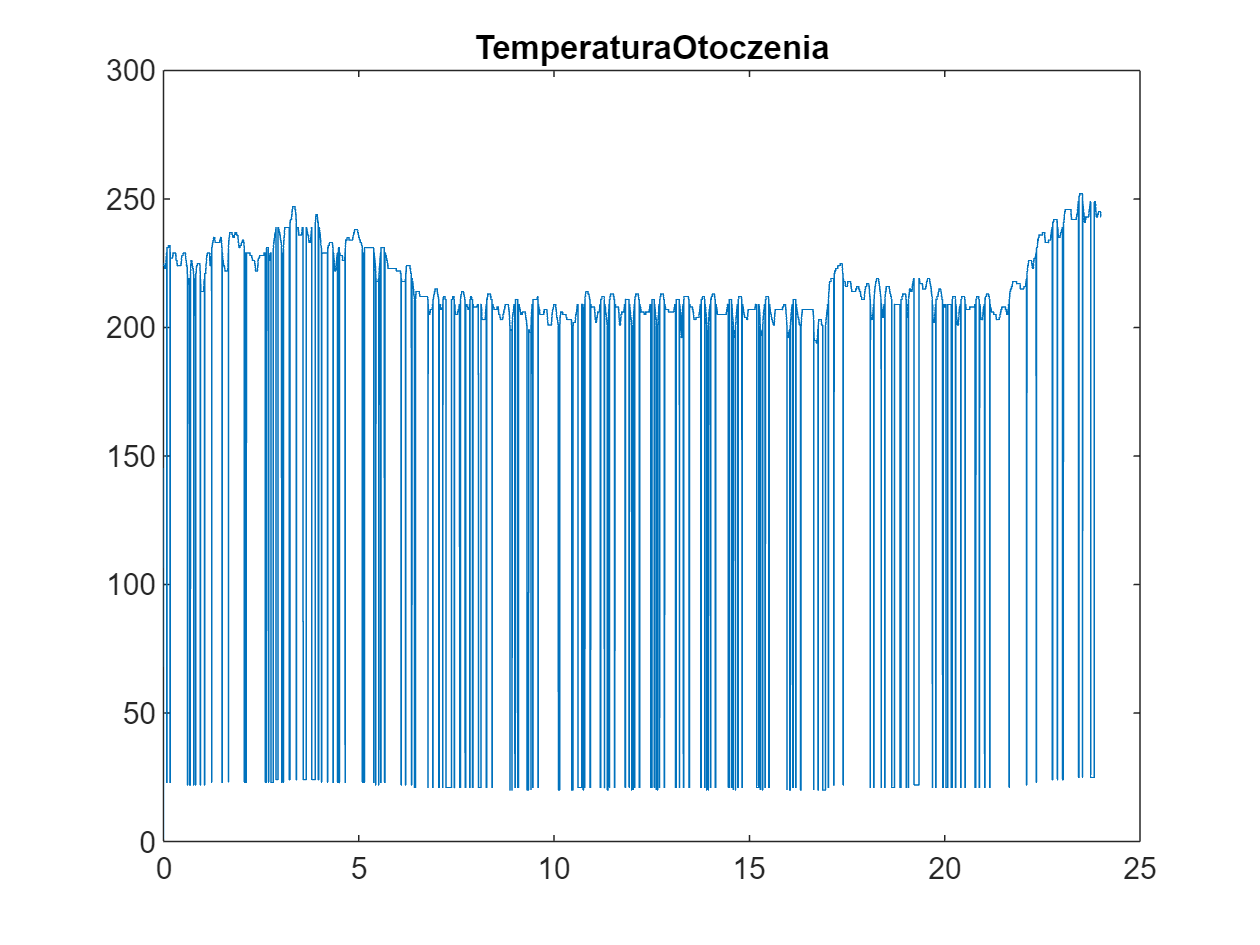

plot(t/(60*60),X(6,:))
title('TemperaturaOtoczenia')

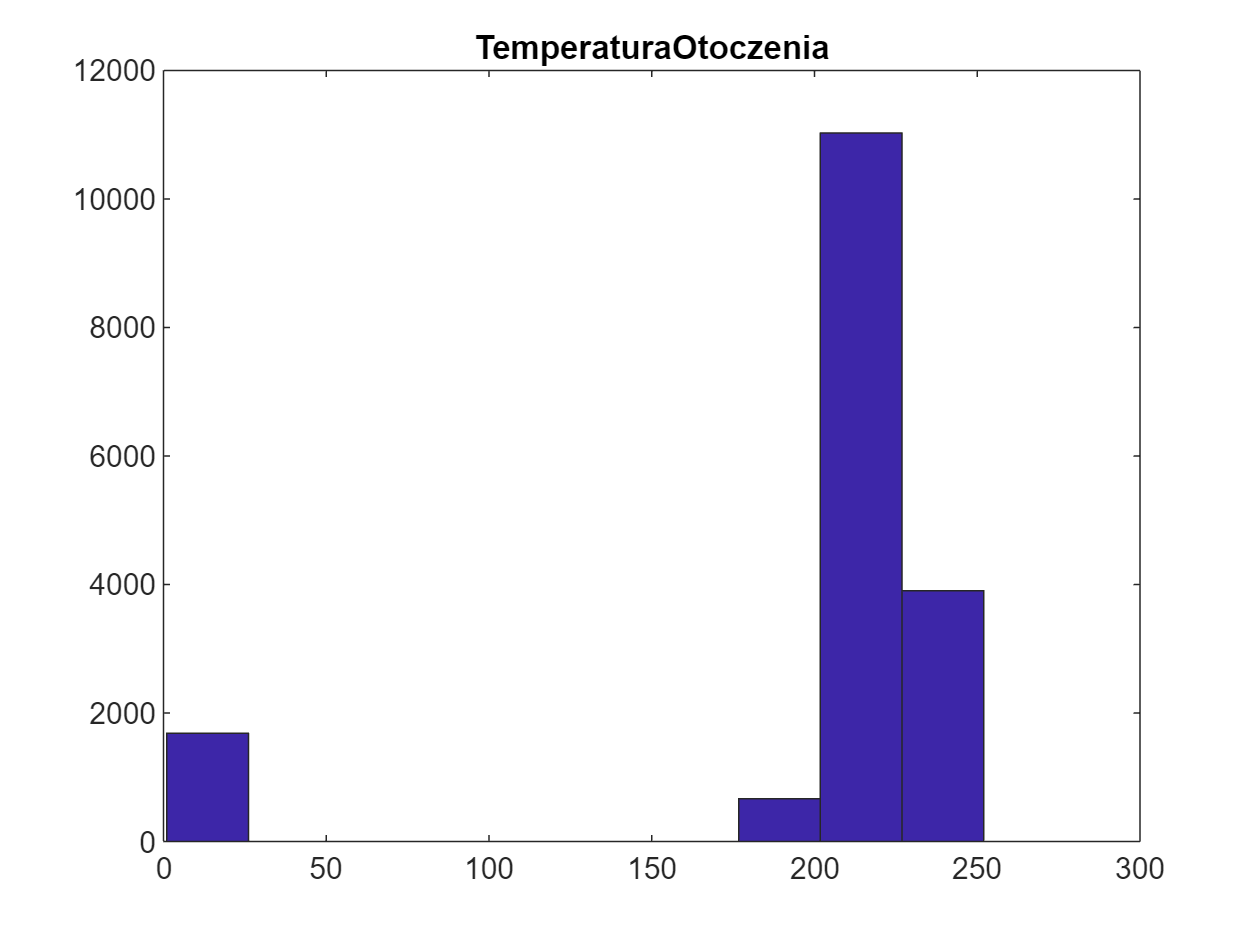

hist(X(6,:))
title('TemperaturaOtoczenia')

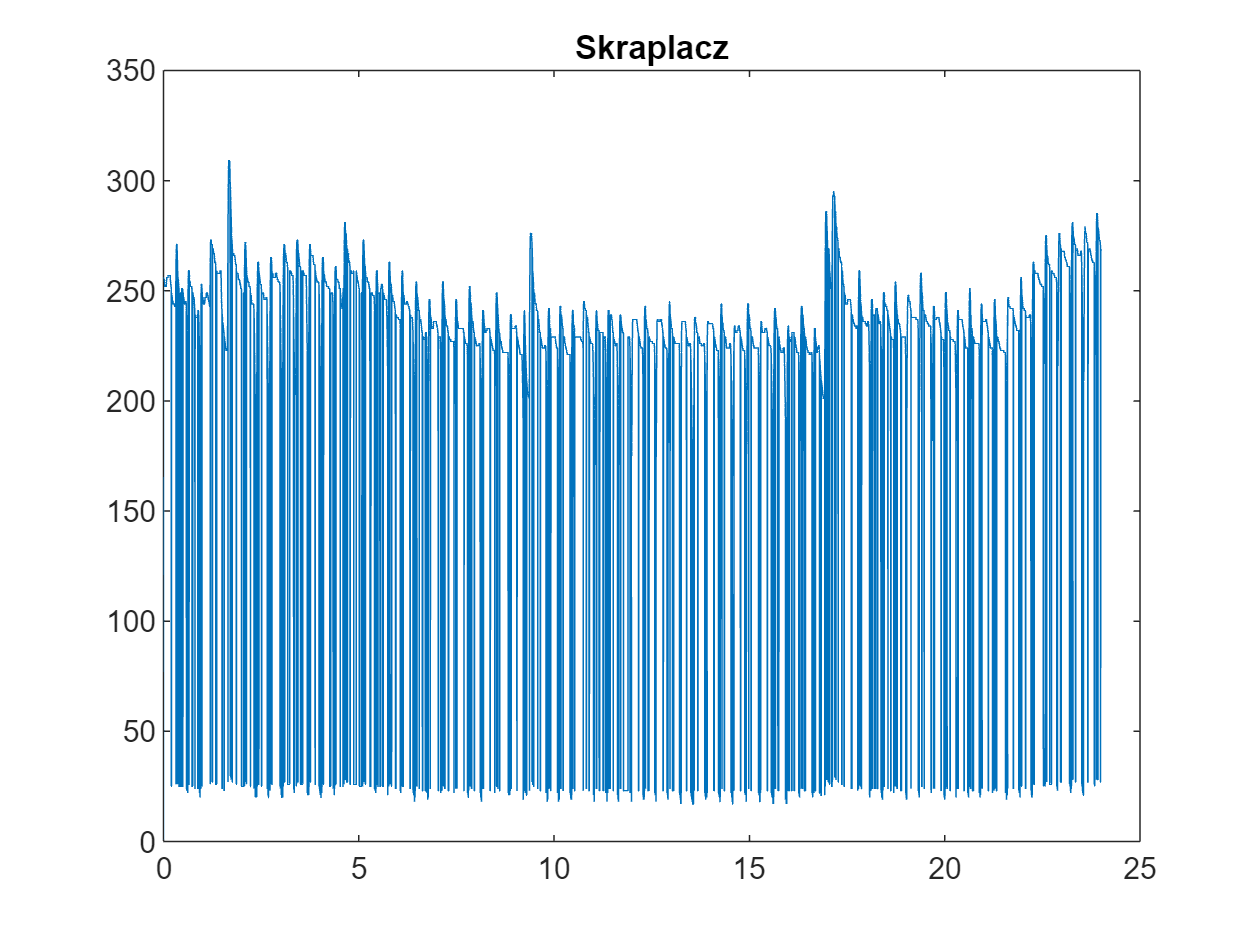

plot(t/(60*60),X(7,:))
title('Skraplacz')

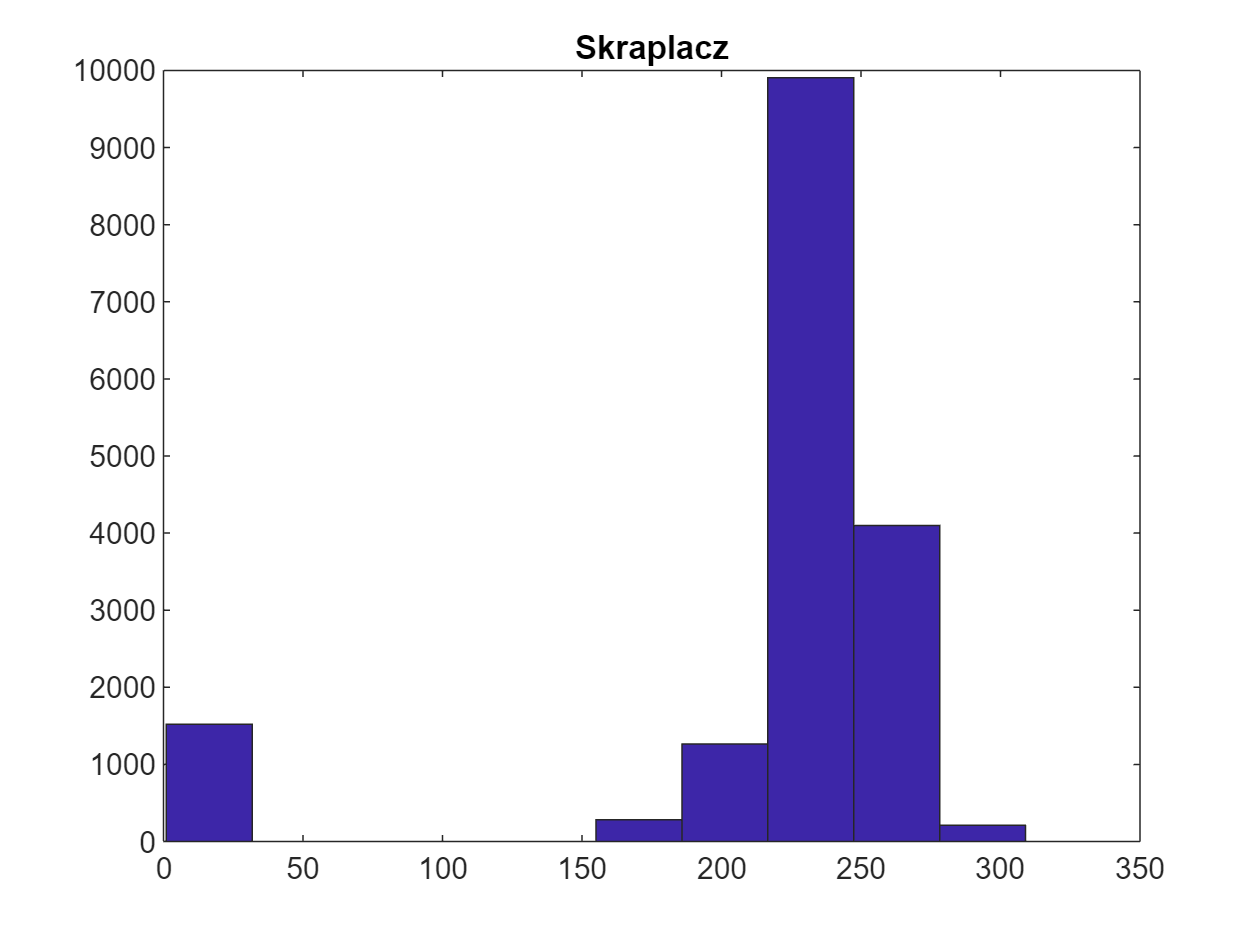

hist(X(7,:))
title('Skraplacz')

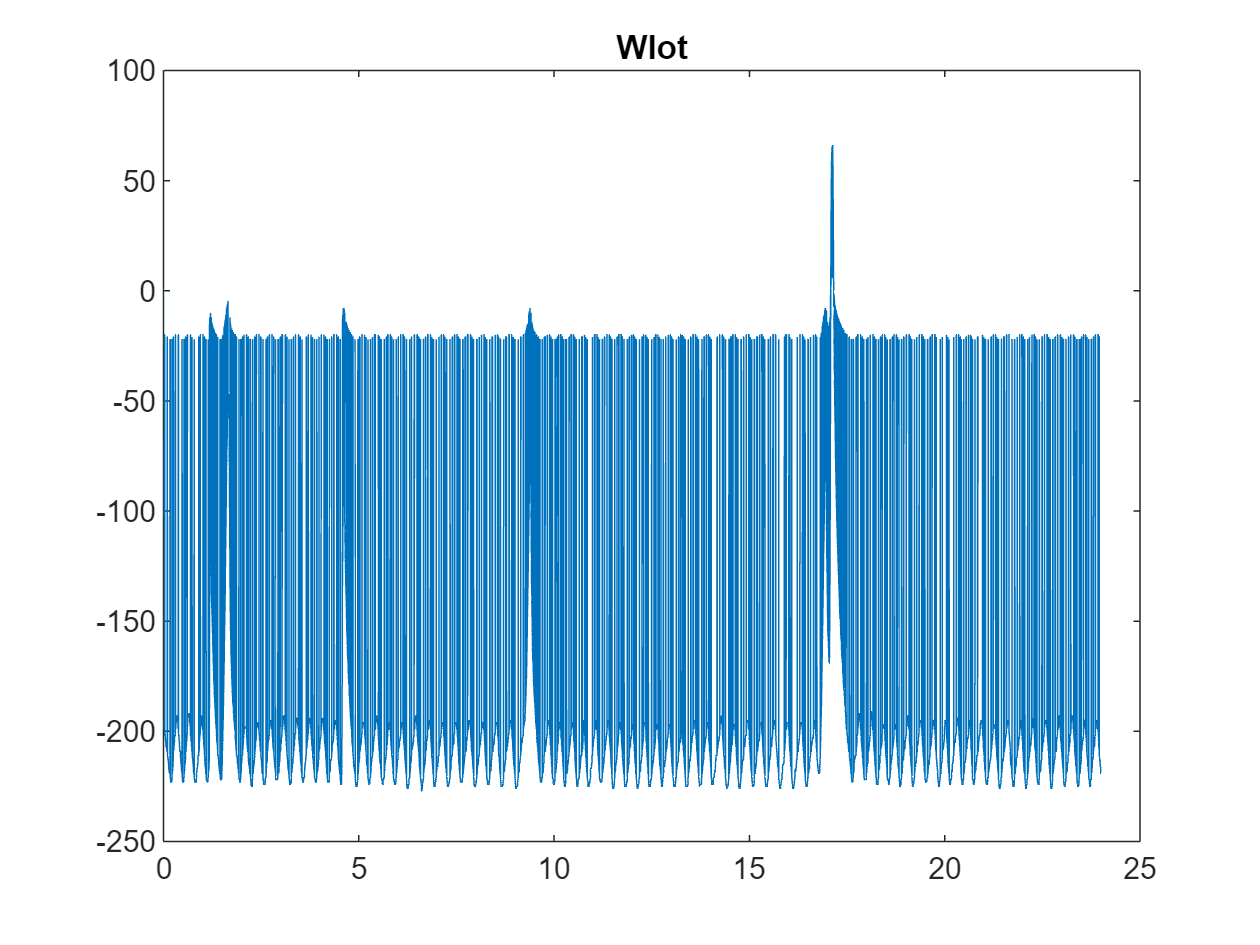

plot(t/(60*60),X(8,:))
title('Wlot')

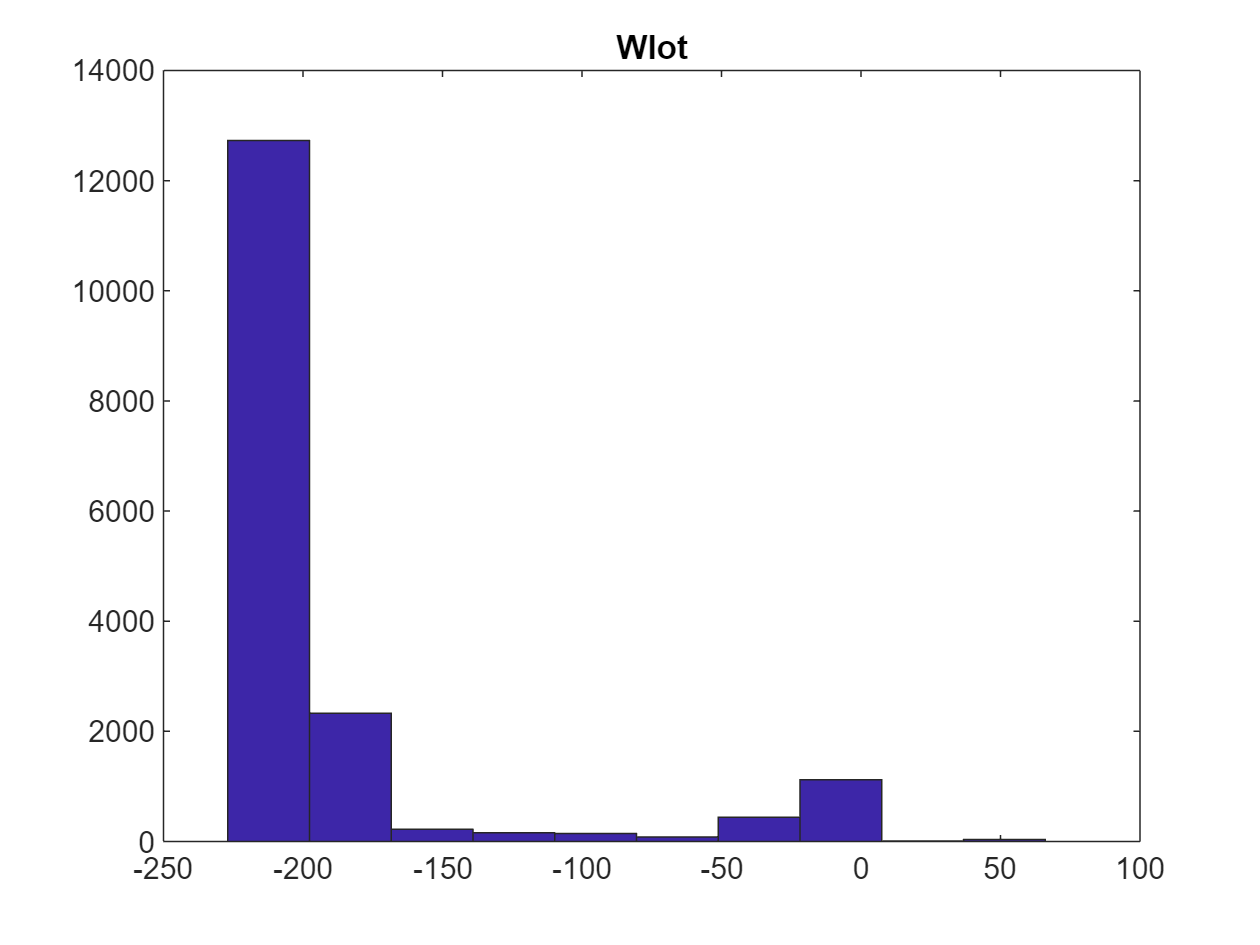

hist(X(8,:))
title('Wlot')

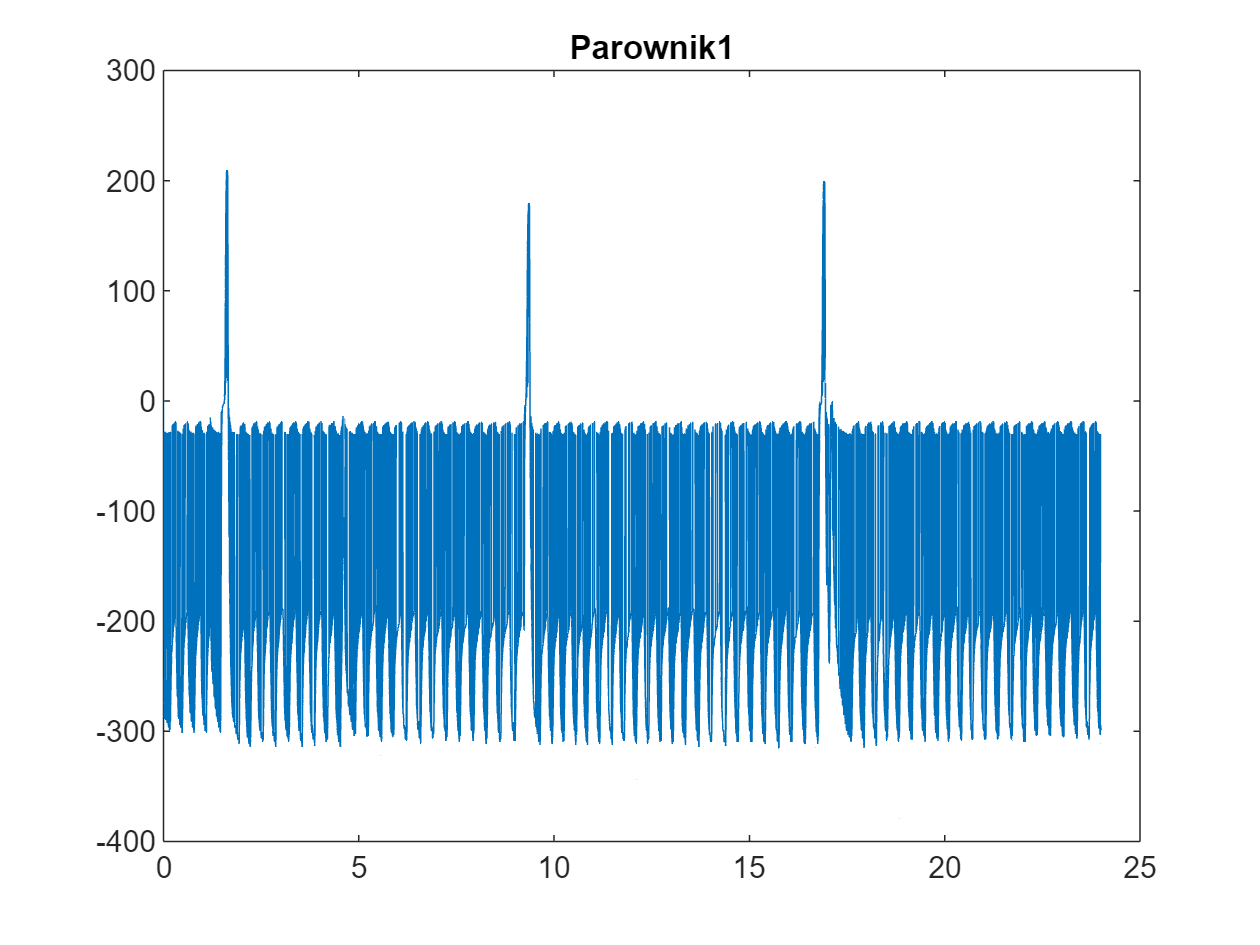

plot(t/(60*60),X(9,:))
title('Parownik1')

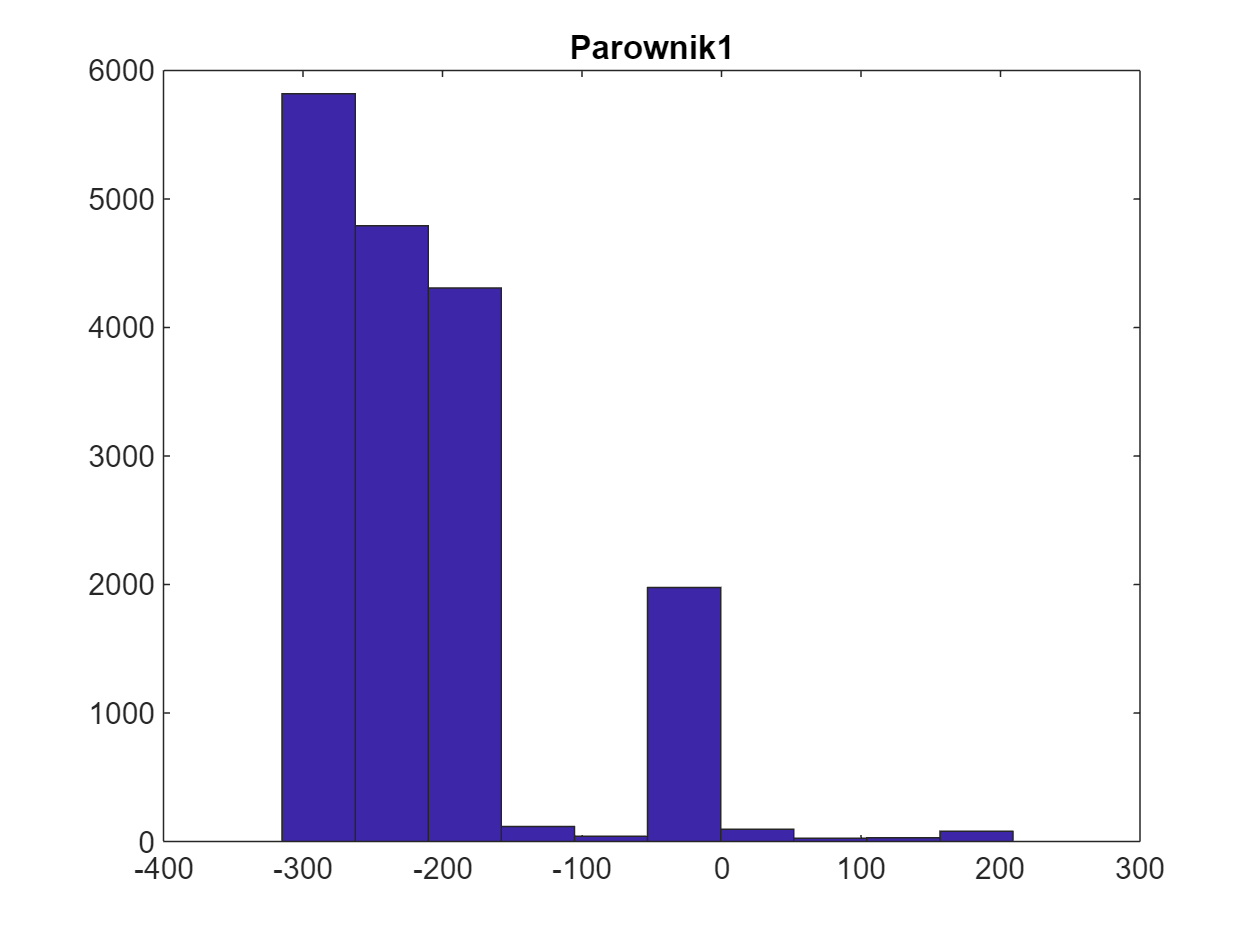

hist(X(9,:))
title('Parownik1')